# Deep Leraning - Deep Neural Network

clc; close all; clear all;


## 1.Data reading

[data, datatxt, dataraw] = xlsread("test.xlsx");
[m n] = size(data);


### 2. Data Normalization and Categorization 

maxValue = max(max(data));
data = data./maxValue;

trainingPortion = 0.8;
rIndex = randperm(m)';
trainIndex = floor(m.*trainingPortion);

trainingData = data(rIndex(1:trainIndex),:);
testData = data(rIndex(trainIndex+1:m),:);

xTrain = trainingData(:,1:20);
yTrain = trainingData(:,21:25);

xTest = testData(:,1:20);
yTest = testData(:,21:25);


### 4. Architecture of Deep Learning

layers = [
    featureInputLayer(20,"Name","featureinput")
    fullyConnectedLayer(25,"Name","fc_1")
    tanhLayer("Name","tanh_1")
    fullyConnectedLayer(20,"Name","fc_3")
    tanhLayer("Name","tanh_3")
    fullyConnectedLayer(15,"Name","fc_2")
    tanhLayer("Name","tanh_2")
    fullyConnectedLayer(10,"Name","fc_4")
    tanhLayer("Name","tanh_4")
    fullyConnectedLayer(8,"Name","fc_5")
    tanhLayer("Name","tanh_5")
    fullyConnectedLayer(6,"Name","fc_6")
    tanhLayer("Name","tanh_6")
    fullyConnectedLayer(5,"Name","fc_7")
    regressionLayer("Name","regressionoutput")];


## 5. Training Options

options = trainingOptions("adam", ...
    MaxEpochs=500, ...
    InitialLearnRate=0.01,...
    Plots="training-progress");


### 6. Deep Learning

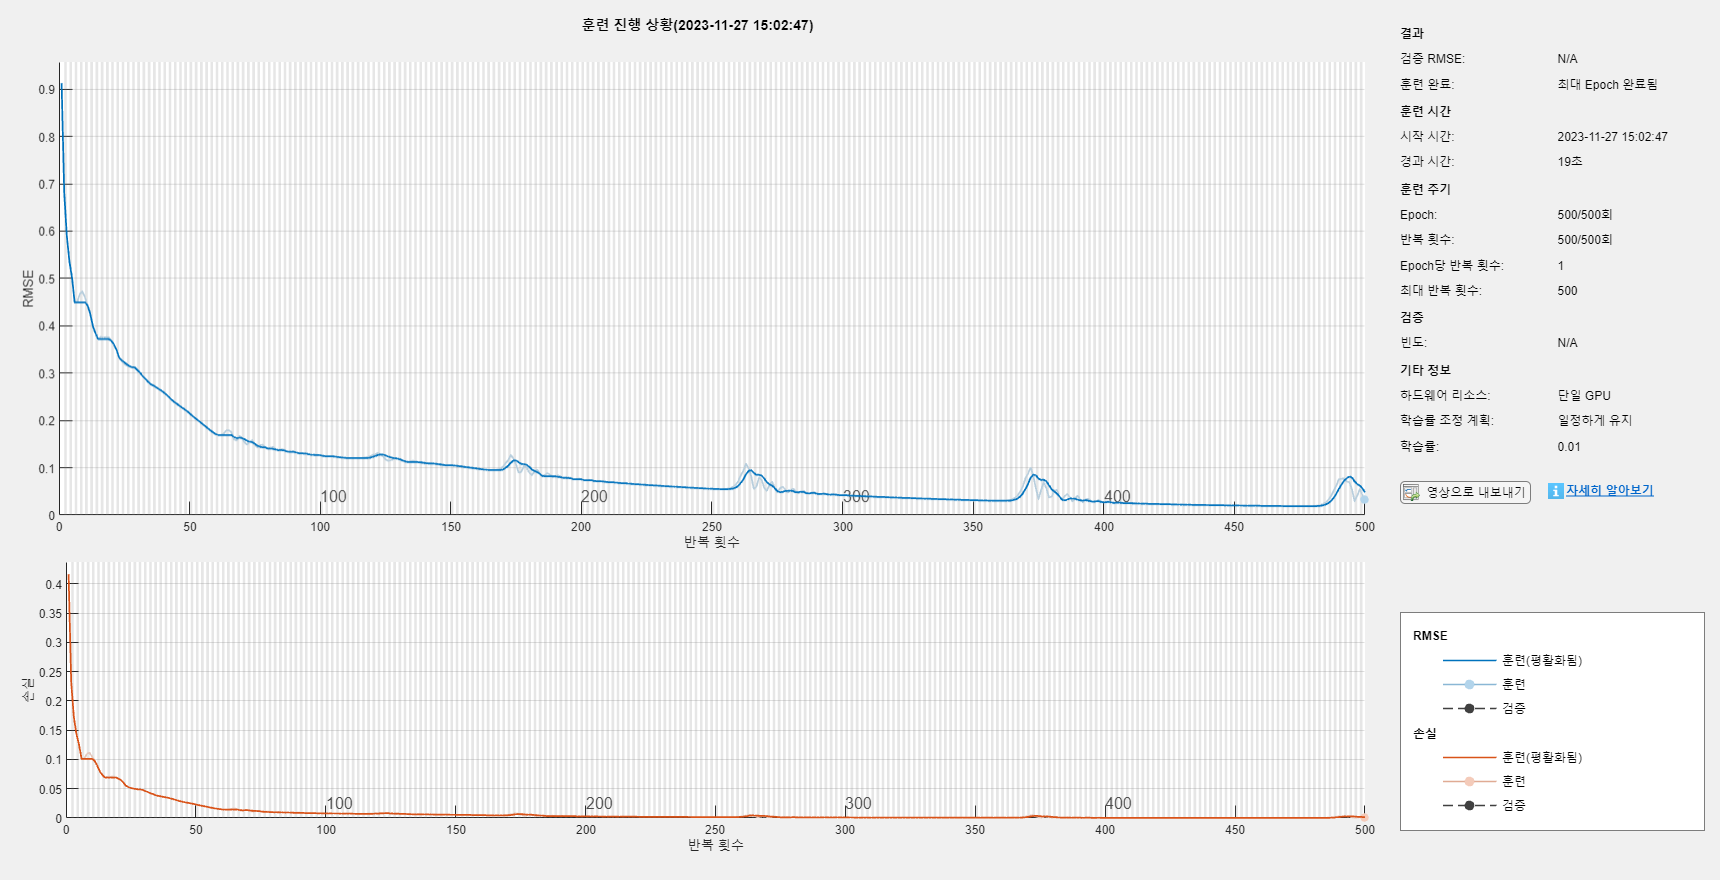

단일 GPU에서 훈련합니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　ＲＭＳＥ　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０２　｜　　　　　　　　　０．９１　｜　　　　　　　　０．４　｜　　　０．０１００　｜
｜　　　　　　５０　｜　　　　　　５０　｜　　　　　００：００：０５　｜　　　　　　　　　０．２２　｜　　　　２．３ｅ－０２　｜　　　０．０１００　｜
｜　　　　　１００　｜　　　　　１００　｜　　　　　００：００：０６　｜　　　　　　　　　０．１３　｜　　　　８．０ｅ－０３　｜　　　０．０１００　｜
｜　　　　　１５０　｜　　　　　１５０　｜　　　　　００：００：０８　｜　　　　　　　　　０．１１　｜　　　　５．５ｅ－０３　｜　　　０．０１００　｜
｜　　　　　２００　｜　　　　　２００　｜　　　　　００：００：０９　｜　　　　　　　　　０．０８　｜　　　　２．９ｅ－０３　｜　　　０．０１００　｜
｜　　　　　２５０　｜　　　　　２５０　｜　　　　　００：００：１１　｜　　　　　　　　　０．０６　｜　　　　１．５ｅ－０３　｜　　　０．０１００　｜
｜　　　　　３００　｜　　　　　３００　｜　　　　　００：００：１３　｜　　　　　　　　　０．０４　｜　　　　８．８ｅ－０４　｜　　　０．０１００　｜
｜　　　　　３５０　｜　　　　　３５０　｜　　　　　００：００：１５　｜　　　　　　　　　０．０３　｜　　　　４．９ｅ－０４　｜　　　０．０１００　｜
｜　　　　　４００　｜　　　　　４００　｜　　　　　００：００：１６　｜　　　　　　　　　０．０３　｜　　　　３．３ｅ－０４　｜　　　０．０１０


[net, info] = trainNetwork(xTrain,yTrain,layers,options);

## 7. Validation

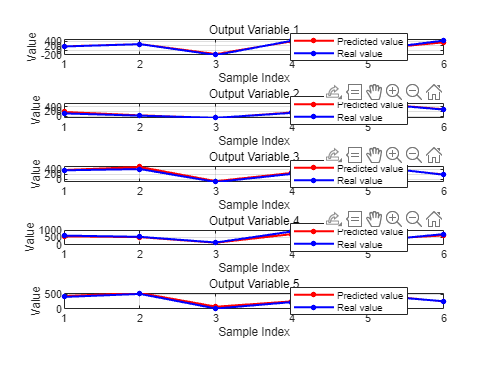

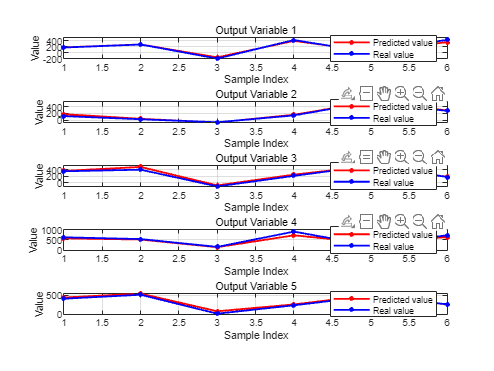

yPredict = predict(net,xTest);
yPredict = yPredict.*maxValue;
yTest = yTest.*maxValue;

figure(3);
set(gcf, 'color', [1 1 1]);

numOutputs = size(yTest, 2);

for i = 1:numOutputs
    subplot(numOutputs, 1, i);
    plot(yPredict(:,i), 'r.-', 'LineWidth', 1.5, 'MarkerSize', 12);
    hold on;
    plot(yTest(:,i), 'b.-', 'LineWidth', 1.5, 'MarkerSize', 12);
    hold off;
    
    grid on;
    title(['Output Variable ' num2str(i)]);
    xlabel('Sample Index');
    ylabel('Value');
    
    legend('Predicted value', 'Real value', 'Location', 'best');
end

## 8. Prediction


% realX = [1,34, ...]
% y = predict(net,realX);











